# EFMouse: 1 x 4 montage

EFMouse is a Matlab tool for electric field modelling in the mouse brain.

This notebook reproduces results for the 1 x 4 high-definition montage in: 

Sanchez-Romero R, Akyuz S, Krekelberg B (2025) EFMouse: A toolbox to model stimulation-induced electric fields in the mouse brain. PLoS Comput Biol 21(9): e1013471. https://doi.org/10.1371/journal.pcbi.1013471

The notebook is also an introductory tutorial to simulate other montages.

Developed by Ruben Sanchez-Romero, Bart Krekelberg and Sibel Akyuz

Rutgers-Newark, Center for Molecular and Behavioral Neuroscience (CMBN)

For support open an issue in https://github.com/klabhub/EFMouse/issues

## Introduction

EFMouse combines several elements from previous work: 

- Anatomical data from the Digimouse project.

- A refined finite element mesh of the Digimouse by Alekseichuk et al., (2019), *Neuroimage*. 

- Matlab code and inspiration from the ROAST toolbox.

- The GetDP finite element method (FEM) solver (v 3.5.0).

- The Allen mouse brain atlas.

Key new functionality includes: 

- Positioning electrodes in arbitrary locations in and on the mouse body.

- Modeling craniotomies in the mouse skull.

- Analyzing the electric field in user-defined regions of interest

- Analyzing the electric field in brain regions defined in the Allen mouse atlas.

- A measure of relative focality of the electric field.

- A measure of direction homogeneity of the electric field.

For details see Sanchez-Romero et al., (2025) and *EFMouse.m* Matlab code.

## Typical workflow

The typical workflow to generate a model consists of several stages

- Stage.INIT           : Initialize. 

- Stage.MESH       : Define elecrodes and (optionally) a craniotomy.

- Stage.EXPORT   : Export files for the FEM solver GetDP.

- Stage.GETDP     : Run the FEM solver.

- Stage.ATLAS      : Map the results to the Allen mouse atlas.

### Stage INIT: Initialize

We start by setting up the basic parameters of the `EFMouse` object:

o = EFMouse; % Create a default empty object of the class EFMouse
o.ID = '1x4';  % A name/tag for this simulation.
o.dir = '/Users/rubensanchez/desktop/efmouse_sim/1x4'; % Results and the object (1x4.mat) will be saved here.
o.log  = true;  % Create a log file.

Note: The log file is created but doesn't update when running a simulation from a notebook (like here). It will properly update when running EFMouse directly from the Matlab command line.

`initialize()` creates the folder to store the results. With `overwrite=true`, anything in this folder will be deleted.

o.initialize(overwrite=true); 

The initialized `EFMouse` o Object contains the default mouse mesh (without stimulation electrodes). Let's visualize it.

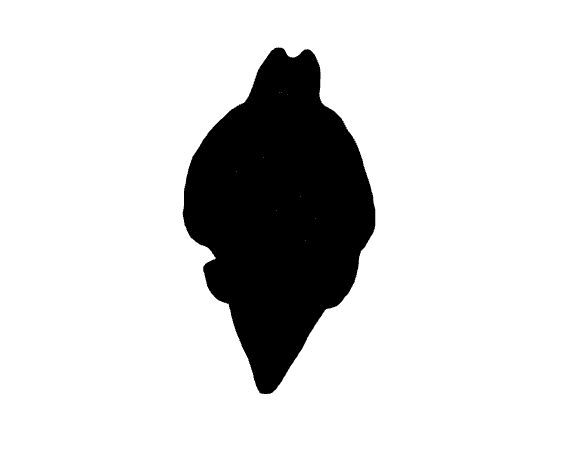

plotMesh(o,tissue="gray")

The mesh is pretty dense, so it may look like a black blob. The olfactory bulbs are visible on the top. In a regular figure window, you can use the Matlab figure tools to rotate or zoom. (You can also adapt the `plotMesh()` function in *EFMouse.m* to modifiy the figure directly.)

### Stage MESH: Create electrodes and (optionally) a craniotomy

Now we define a 4x1 center-surround stimulation montage, targeting visual areas.  The surface type is an electrode that is placed on top of the animal (simulating how gel would be placed on the skin).

o.addElectrode(tag = "Anode",current = +0.2,type="surface",shape="circle",center= [-3.5,27.5,6],radius=0.6, thickness=1);
o.addElectrode(tag = "Anterior",current = -0.05,type="surface",shape="circle",center= [-3.5,30,6],radius=0.6, thickness=1);
o.addElectrode(tag = "Posterior",current = -0.05,type="surface",shape="circle",center= [-3.5,25,6],radius=0.6, thickness=1);
o.addElectrode(tag = "Lateral",current = -0.05,type="surface",shape="circle",center= [-6,27.5,4],radius=0.6, thickness=1);
o.addElectrode(tag = "Medial",current = -0.05,type="surface",shape="circle",center= [-1,27.5,6],radius=0.6, thickness=1);

To update the model with the electrodes, we run the pipeline to Stage.MESH. With `show=true`, this also opens a figure for inspection of the mesh:

Compute stage MESH
EF Mouse Model (label: 1x4) in directory /Users/rubensanchez/desktop/efmouse_sim/1x4 (stage=INIT).
-Meshing 5 electrodes-
Closest skin node is 0.4 away from the Anode electrode target position.
Closest skin node is 0.7 away from the Anterior electrode target position.
Closest skin node is 0.1 away from the Posterior electrode target position.
Closest skin node is 0.6 away from the Lateral electrode target position.
Closest skin node is 0.3 away from the Medial electrode target position.


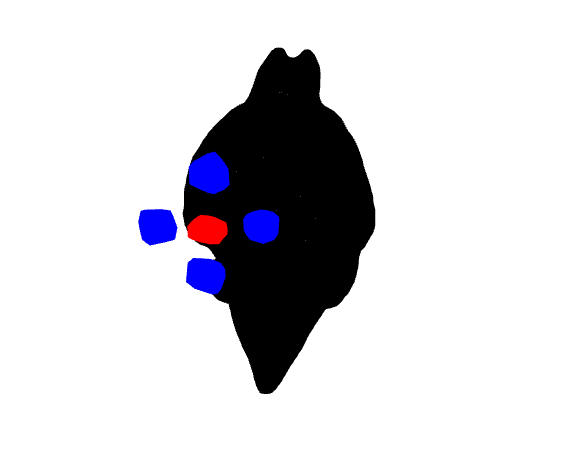

Stage MESH complete - 9.5110 seconds 


o.run(targetStage=Stage.MESH,show=true)

This mesh shows the electrodes in red (anode) and blue (cathode).

### Stage EXPORT: Export the mesh and model

Up until this stage, all changes were internal to the Matlab object (saved in 1x4*.mat*), now we export files that the FEM solver GetDP can read. The *.msh* file contains information on the mesh (all the nodes, elements, labels and boundaries), and the *.pro* file tells GetDP which partial differential equations (PDE) model it needs to solve in this mesh.

o.run(targetStage=Stage.EXPORT)

Compute stage EXPORT
----Starting saveMesh...19-Jun-2025 11:16:12
----saveMesh elapsed time: 11.6159 seconds

----Starting savePro...19-Jun-2025 11:16:23
----savePro elapsed time: 0.0146 seconds

Stage EXPORT complete - 8.1382 seconds 


For troubleshooting, have a look at the *.pro* file in the project folder; it contains all the model specifications, including conductivity (in siemens per meter S/m) for the different tissues/elements.

type(file(o,"PRO"))

/* 
 .pro file created by EFMouse on 19-Jun-2025 11:16:23 
 ID: 1x4 
 Dir: /Users/rubensanchez/desktop/efmouse_sim/1x4 
 */

Group {

gray = Region[1];
csf = Region[2];
bone = Region[3];
skin = Region[4];
eye = Region[5];
Anode = Region[6];
Anterior = Region[7];
Posterior = Region[8];
Lateral = Region[9];
Medial = Region[10];
boundaryAnode = Region[11];
boundaryAnterior = Region[12];
boundaryPosterior = Region[13];
boundaryLateral = Region[14];
boundaryMedial = Region[15];
DomainC = Region[{gray,csf,bone,skin,eye,Anode,Anterior,Posterior,Lateral,Medial}];
AllDomain = Region[{gray,csf,bone,skin,eye,Anode,Anterior,Posterior,Lateral,Medial,boundaryAnode,boundaryAnterior,boundaryPosterior,boundaryLateral,boundaryMedial}];
}

Function {

sigma[gray] = 0.275;
sigma[csf] = 1.654;
sigma[bone] = 0.01;
sigma[skin] = 0.465;
sigma[eye] = 0.5;
sigma[Anode] = 0.3;
sigma[Anterior] = 0.3;
sigma[Posterior] = 0.3;
sigma[Lateral] = 0.3;
sigma[Medial] = 0.3;
du_dnAnode[] = 110.774083;
du_dnAnterior[] = -1

This file can be opened in the GetDP gui to run it manually, but Stage.GETDP runs it for you.

### Stage GETDP: Run GetDP

It will take GetDP between 15 and 30 minutes to compute the solutions of the Laplace equation (on 2024 Mac or Windows hardware). The results are saved in *_e.pos* and *_v.pos* files (in GetDP format). In the `o` object the results are saved as `.field` and `.voltage`.

o.run(targetStage=Stage.GETDP,show=false);

Compute stage GETDP
Info    : Running '/Users/rubensanchez/Desktop/Klab/EFMouse/lib/getdp-3.5.0/bin/getdpMac /Users/rubensanchez/desktop/efmouse_sim/1x4/1x4.pro -solve EleSta_v -msh /Users/rubensanchez/desktop/efmouse_sim/1x4/1x4.msh -pos Map' [GetDP 3.5.0, 1 node, max. 1 thread]
Info    : Started (Thu Jun 19 11:17:31 2025, Wall = 0.00164914s, CPU = 0.013192s, Mem = 4.27344Mb)
Info    : Initializing Gmsh
Info    : Loading problem definition '/Users/rubensanchez/desktop/efmouse_sim/1x4/1x4.pro'
Info    : Selected Resolution 'EleSta_v'
Info    : Loading Geometric data '/Users/rubensanchez/desktop/efmouse_sim/1x4/1x4.msh'
Info    : System 'Sys_Ele' : Real
□P r e - P r o c e s s i n g . . .□
Info    : Treatment Formulation 'Electrostatics_v'
  0%    : Pre-processing                                          
 10%    : Pre-processing                                          
 20%    : Pre-processing                                          
 30%    : Pre-processing                    

Use the `plotEf()` function to visualize the electric field in the X direction, and then the electric field magnitude.

----Starting plotEf...19-Jun-2025 11:25:21


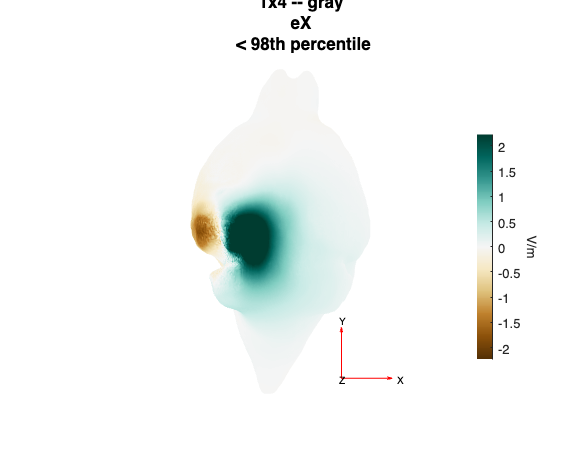

----plotEf elapsed time: 1.9169 seconds


plotEf(o,type='eX',percentile=98, tissue='gray');

----Starting plotEf...19-Jun-2025 11:25:23


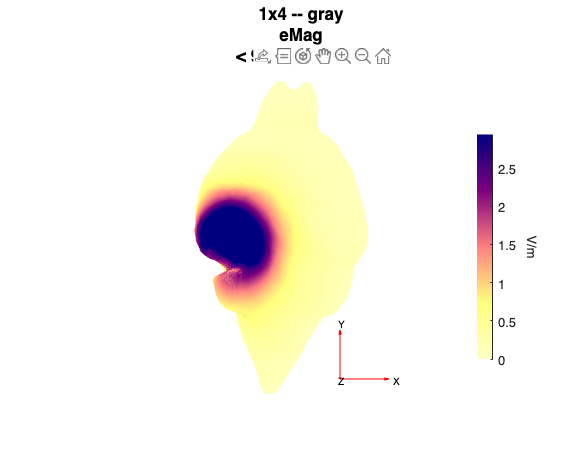

----plotEf elapsed time: 0.7774 seconds


plotEf(o,type='eMag',percentile=98,tissue='gray')

We can also use `plotEf()` to visualize a brain slice perpendicular to a given axis. Here we show a frontal/coronal plane slice (perpendicular to the y axis) in the position of the anode electrode, a sagittal slice and a horizontal slice. 

----Starting plotEf...19-Jun-2025 11:31:08


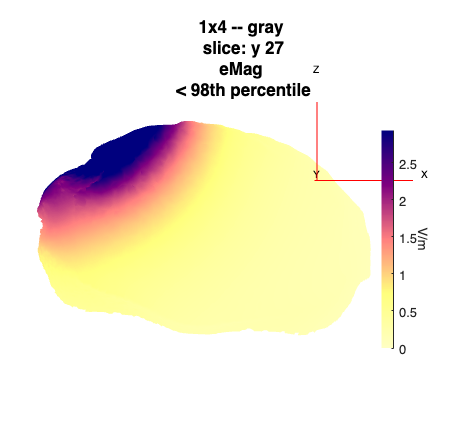

----plotEf elapsed time: 0.6849 seconds


plotEf(o,type='eMag',percentile=98,tissue='gray',slice = true, slice_ax = "y",slice_pos = 27)

----Starting plotEf...19-Jun-2025 11:31:08


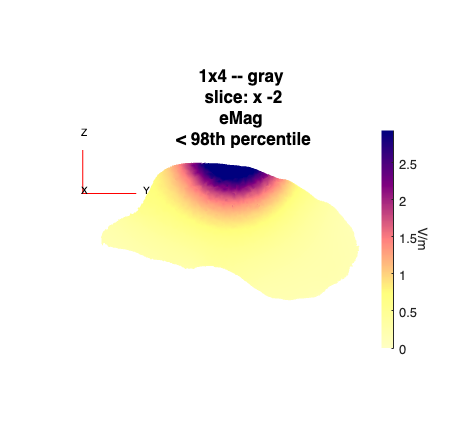

----plotEf elapsed time: 0.4648 seconds


plotEf(o,type='eMag',percentile=98,tissue='gray',slice = true, slice_ax = "x",slice_pos = -2)

----Starting plotEf...19-Jun-2025 11:31:09


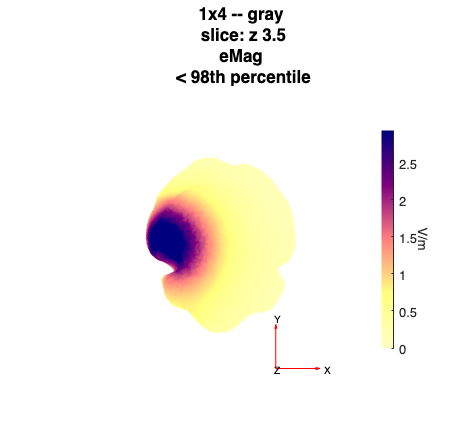

----plotEf elapsed time: 0.4392 seconds


plotEf(o,type='eMag',percentile=98,tissue='gray',slice = true, slice_ax = "z",slice_pos = 3.5)

### **Tissue Based Analysis**

In general, we focus on the brain, but if necessary, we can compute electric field estimates for the rest of the mouse body for a full characterization of the anatomical effects of the electrical stimulation protocol.

See Sanchez-Romero et al., (2025) for a full description of the electric field metrics.

summary = analyzeTissue(o,["skin" "gray"]);

----Starting analyzeTissue...19-Jun-2025 11:33:03
Electric field summary statistics for skin tissue
              mean         median        std         min         max  
            _________    ___________    ______    __________    ______

    eX       0.011945    -7.7172e-06    2.3153       -107.16     158.9
    eY      0.0063373     5.5934e-08    1.8954        -151.3    149.63
    eZ      -0.080097    -9.3972e-05     3.239       -247.47    65.915
    eMag       0.3283      0.0017611    4.3981    5.4284e-09    274.42

[Homogeneity ranges from 0 to 1]
Homogeneity = 0.4775, for ef_norm_mean: (-0.250 0.034 -0.405)

Electric field summary statistics for gray tissue
              mean       median       std

### ROI Analysis

Now that we have the field estimates for each node in the mesh, we can do an ROI based analysis. For instance, a box ROI.

For the *relative focality*, the reference area is the rest of the gray tissue. 

See Sanchez-Romero et al.(2025), for definitions of *relative focality* and *homogeneity*.

roi.shape = 'box';
roi.center = [-3.5 27.5 3.5];
roi.width = 2;  % Lateral/Medial
roi.length = 2; % Posterior/Anterior
roi.thickness =1;  % Inferior/Superior
summary = analyzeRoi(o,roi,plot=true,foc_percentile_max=99.9,foc_threshold=40); % Define values for relative focality metric.

----Starting analyzeRoi...30-Jun-2025 11:49:13
Electric field summary statistics for a box roi in gray
              mean       median       std        min        max  
            ________    ________    _______    _______    _______

    eX      -0.31857    -0.31385    0.72408    -1.9121     1.5151
    eY       0.33103     0.38283    0.62611    -1.3668     2.1037
    eZ       -2.3046     -2.1785    0.58995    -4.5109    -1.1986
    eMag      2.5282      2.4118    0.62771     1.4428     4.5434

[Relative focality ranges from 0 to 1]
Relative focality = 0.9612, with 160508 reference nodes (cutoff: eMag > 40.00% of the target area max (99.90th percentile))
[Homogeneity ranges from 0 to 1]
Homogeneity = 0.9304, for ef_norm_mean: (-0.121 0.129 -0.913)


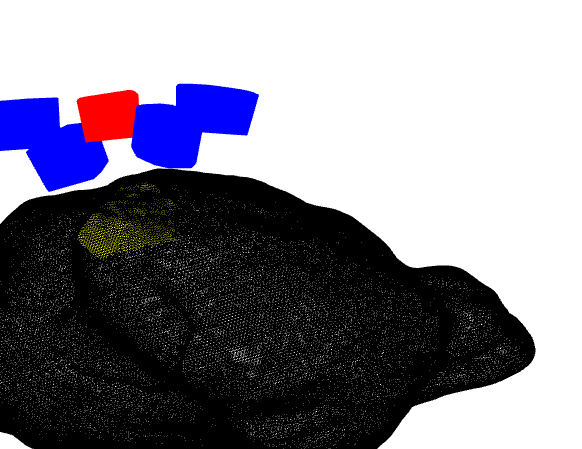

% Rotate and zoom to view the (yellow) box ROI underneath the stimulation electrode.
xlim([-3.31 1.13])
ylim([26.3 36.1])
zlim([2.31 4.98])
view([62.61 27.62])

For comparison, define an analogous box ROI but in the right hemisphere.

roiRight = roi;
roiRight.center(1)  =-1* roi.center(1)

roiRight = struct with fields:
        shape: 'box'
       center: [3.5000 27.5000 3.5000]
        width: 2
       length: 2
    thickness: 1


summary = analyzeRoi(o,roiRight,plot=true,foc_percentile_max=99.9,foc_threshold=40);

----Starting analyzeRoi...30-Jun-2025 11:49:15
Electric field summary statistics for a box roi in gray
              mean        median        std         min         max   
            _________    _________    ________    ________    ________

    eX        0.14214      0.14212    0.041943    0.042962     0.24768
    eY         0.1112      0.11236    0.018523    0.056264     0.15984
    eZ      -0.026263    -0.029507    0.019432    -0.07757    0.036035
    eMag      0.18494      0.18212    0.039187     0.10404     0.28543

[Relative focality ranges from 0 to 1]
Relative focality = 0.0887, with 160925 reference nodes (cutoff: eMag > 40.00% of the target area max (99.90th percentile))
[Homogeneity ranges from 0 to 1]
Homogeneity = 0.9852, for ef_norm_m

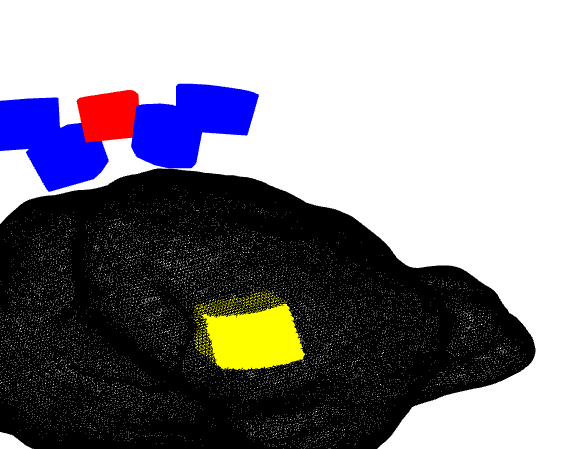

% Rotate and zoom to view the (yellow) box ROI in the right hemisphere
xlim([-3.31 1.13])
ylim([26.3 36.1])
zlim([2.31 4.98])
view([62.61 27.62])

### Stage ATLAS: Volumetric/Atlas Analysis

The mesh coordinates are not particularly intuitive, and you may want to estimate electric fields in specific brain areas (as defined in an atlas). EFMouse does this in reference to the Allen Mouse Brain Atlas. 

To use this, we first have to map the mesh-based results to the Allen Atlas. This is Stage ATLAS of the pipeline. This stage first exports the mesh-based results to a volume (using linear interpolation) and then uses the FLIRT tool in FSL to transform this volume to the coordinates of the Allen Atlas. Note that the alignment between the Digimouse mesh and the Allen Atlas is not perfect because they are based on different imaging modalities (and different mouse strains). (See Sanchez-Romero et al., (2025), for more details.) 

This will fail if FSL is not installed.

o.run(targetStage=Stage.ATLAS,startStage=Stage.ATLAS)

Compute stage ATLAS
----Starting computeVoxelSpace...19-Jun-2025 11:35:38
----Exporting to NIFTI volumes 
---/Users/rubensanchez/desktop/efmouse_sim/1x4/1x4_efm.nii.gz created
---/Users/rubensanchez/desktop/efmouse_sim/1x4/1x4_efX.nii.gz created
---/Users/rubensanchez/desktop/efmouse_sim/1x4/1x4_efY.nii.gz created
---/Users/rubensanchez/desktop/efmouse_sim/1x4/1x4_efZ.nii.gz created
----computeVoxelSpace elapsed time: 8.0023 seconds
Stage ATLAS complete - 16.0120 seconds 


### Atlas Based Analysis

Once stage ATLAS has completed we can query electric fields based on a region that is defined in the Allen Atlas. For instance: 'Visual areas' for the left hemisphere.

For the relative focality the reference area is the rest of the Allen atlas "Isocortex".

T = analyzeAtlas(o,"Visual areas",hemisphere="left",foc_threshold=40,foc_percentile_max=99.9,foc_reference='Isocortex');

----Starting analyzeAtlas...30-Jun-2025 11:51:07
Area: Visual areas (1.0% of brain) , hemisphere left 
             mean      median      std         min        max  
            _______    _______    ______    _________    ______

    eX       1.7202     1.9887    1.3311      -1.4344    4.4274
    eY      0.36229    0.33138    1.0561      -2.1406    3.3212
    eZ      -2.5716    -2.5445     1.227      -5.8689         0
    eMag     3.5418     3.5872    1.2559    0.0013875    6.5304

[Relative focality ranges from 0 to 1]
Relative focality = 0.9757, with 92410 reference voxels (cutoff: eMag > 40.00% of the target area max (99.90th percentile))
[Homogeneity ranges from 0 to 1]
Homogeneity = 0.8617, for ef_norm_mean: (0.473 0.098 -0.713)
----analyzeAtlas

For comparison, we can query results for the right hemisphere, which is contra-lateral from the targeted area.

T = analyzeAtlas(o,"Visual areas",hemisphere="right",foc_threshold=40,foc_percentile_max=99.9,foc_reference='Isocortex');

----Starting analyzeAtlas...30-Jun-2025 11:51:07
Area: Visual areas (1.0% of brain) , hemisphere right 
              mean       median        std          min          max  
            ________    _________    ________    __________    _______

    eX        0.2196       0.2235      0.1167    0.00020504    0.48481
    eY       0.13506      0.13923    0.065983    0.00016788    0.30262
    eZ      0.028144    0.0042193    0.075726     -0.095572    0.29784
    eMag       0.268      0.26794     0.13878    0.00026594    0.60635

[Relative focality ranges from 0 to 1]
Relative focality = 0.4450, with 92457 reference voxels (cutoff: eMag > 40.00% of the target area max (99.90th percentile))
[Homogeneity ranges from 0 to 1]
Homogeneity = 0.9656, for ef_norm_

## Tips and Tricks

- The run function can be called with any `targetStage` from Stage.INIT to Stage.ATLAS. Stages that have already been completed will not be run again, and all stages that need to be completed to reach the `targetStage` will be completed in turn.

- IMPORTANT: To continue working with a model from a previous Matlab session, you create an `EFMouse` object with the `dir` and `ID` input arguments to specify the folder with the (previously saved) results and the ID of the montage. For instance, to open the simulation from the tutorial at the stage where it was last saved:

o = EFMouse(dir='/Users/rubensanchez/desktop/efmouse_sim/1x4',ID='1x4')

o = EF Mouse Model (label: 1x4) in directory /Users/rubensanchez/desktop/efmouse_sim/1x4 (stage=ATLAS).